# Elaborazione relazione 5

## Dati

R_A = [12 24 39 54 82 136];
R_B = ones(1,6).*(12);
C_1 = 150*10^(-9);
C_2 = 68*10^(-9);

## Misure

T_meas_1 = [3.771 5.048 6.502 8.325 11.250 17.180]; % in ms
T_meas_2 = [1.710 2.277 2.962 3.743 5.069 7.762]; % in ms
dc_meas_1 = [66.52 74.94 80.54 84.77 88.71 92.61]; % in percentuale
dc_meas_2 = [66.46 74.95 80.48 84.90 88.73 92.60]; % in percentuale

## Calcoli

% C1
t1_1 = (R_A+R_B)*C_1*log(2).*10^6; % in ms
t2_1 = R_B*C_1*log(2).*10^6; % in ms
T_calc_1 = (t1_1 + t2_1); % in ms
dc_calc_1 = (t1_1./T_calc_1)*100; % in percentuale
% C2
t1_2 = (R_A+R_B)*C_2*log(2).*10^6; % in ms
t2_2 = R_B*C_2*log(2).*10^6; % in ms
T_calc_2 = (t1_2 + t2_2); % in ms
dc_calc_2 = (t1_2./T_calc_2)*100; % in percentuale

## Grafico 1

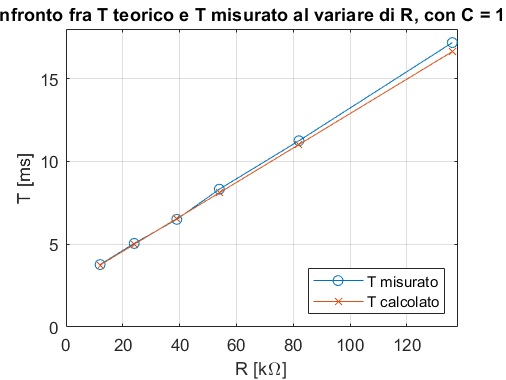

% Confronto T 1 calc vs 1 meas
figure
plot(R_A,T_meas_1,'-o')
hold on
grid on
plot(R_A,T_calc_1,'-x')
title('Confronto fra T teorico e T misurato al variare di R, con C = 150nF')
xlabel('R [k\Omega]'); ylabel('T [ms]')
ylim([0 18]);
xlim([0 138]);
legend('T misurato','T calcolato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficoT1.png');

## Grafico 2

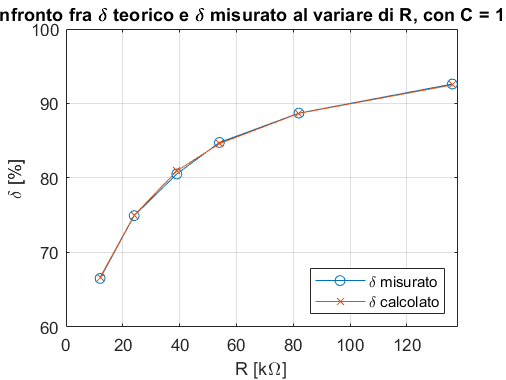

% Confronto DC 1 calc vs 1 meas
figure
plot(R_A,dc_meas_1,'-o')
hold on
grid on
plot(R_A,dc_calc_1,'-x')
title('Confronto fra \delta teorico e \delta misurato al variare di R, con C = 150nF')
xlabel('R [k\Omega]'); ylabel('\delta [%]')
ylim([60 100]);
xlim([0 138]);
legend('\delta misurato','\delta calcolato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficoDC1.png');

## Grafico 3

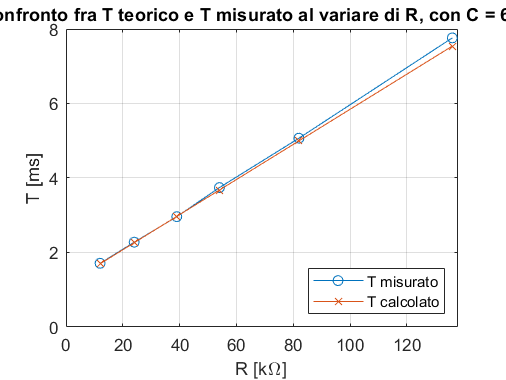

% Confronto T 2 calc vs 2 meas
figure
plot(R_A,T_meas_2,'-o')
hold on
grid on
plot(R_A,T_calc_2,'-x')
title('Confronto fra T teorico e T misurato al variare di R, con C = 68nF')
xlabel('R [k\Omega]'); ylabel('T [ms]')
ylim([0 8]);
xlim([0 138]);
legend('T misurato','T calcolato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficoT2.png');

## Grafico 4

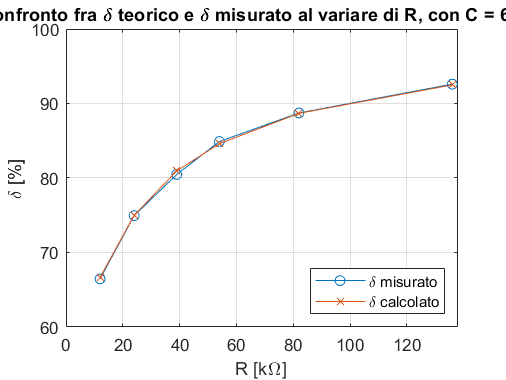

% Contronto DC 2 calc vs 2 meas
figure
plot(R_A,dc_meas_2,'-o')
hold on
grid on
plot(R_A,dc_calc_2,'-x')
title('Confronto fra \delta teorico e \delta misurato al variare di R, con C = 68nF')
xlabel('R [k\Omega]'); ylabel('\delta [%]')
ylim([60 100]);
xlim([0 138]);
legend('\delta misurato','\delta calcolato','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficoDC2.png');

## Grafico 5

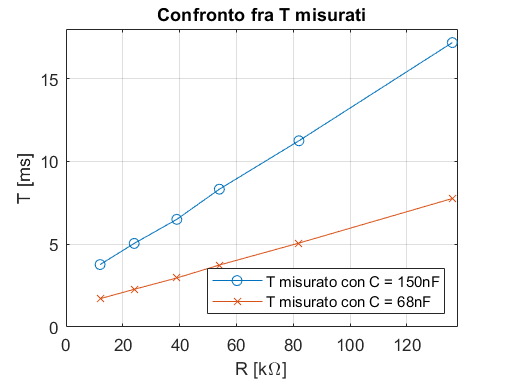

% Contronto T 1 meas vs 2 meas
figure
plot(R_A,T_meas_1,'-o')
hold on
grid on
plot(R_A,T_meas_2,'-x')
title('Confronto fra T misurati')
xlabel('R [k\Omega]'); ylabel('T [ms]')
ylim([0 18]);
xlim([0 138]);
legend('T misurato con C = 150nF','T misurato con C = 68nF','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficoConfrontoT.png');

## Grafico 6

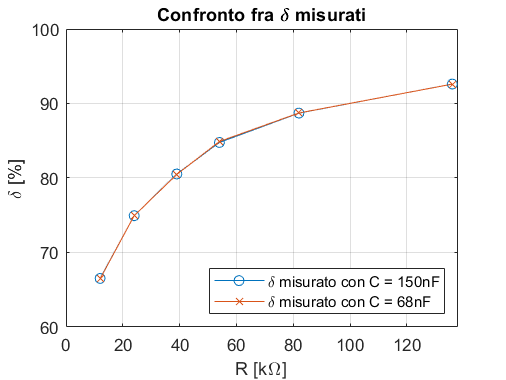

% Contronto DC 1 meas vs 2 meas
figure
plot(R_A,dc_meas_1,'-o')
hold on
grid on
plot(R_A,dc_meas_2,'-x')
title('Confronto fra \delta misurati')
xlabel('R [k\Omega]'); ylabel('\delta [%]')
ylim([60 100]);
xlim([0 138]);
legend('\delta misurato con C = 150nF','\delta misurato con C = 68nF','Location','southeast')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 5\TexFiles\immagini\graficoConfrontoDC.png');